nfft = 2048;
symbols_per_slot = 14;

% Carrier config
carrier = nrCarrierConfig;
carrier.SubcarrierSpacing = 15;
carrier.NSizeGrid = 106;
ofdmInfo = nrOFDMInfo(carrier)

ofdmInfo = struct with fields:
                   Nfft: 2048
             SampleRate: 30720000
    CyclicPrefixLengths: [160 144 144 144 144 144 144 160 144 144 144 144 144 144]
          SymbolLengths: [2208 2192 2192 2192 2192 2192 2192 2208 2192 2192 2192 2192 2192 2192]
              Windowing: 72
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


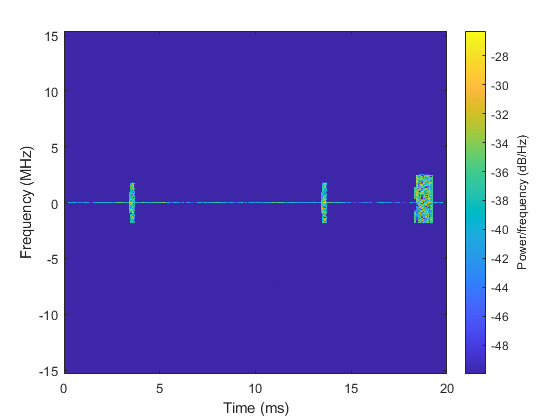


rxOfdmInfo = ofdmInfo;
nfft = rxOfdmInfo.Nfft;
rxSampleRate = rxOfdmInfo.SampleRate;

% rxdata_symbol0;
% rxd0 = rxdata;
% rxdata_symbol1
% rxd0 = cat(1, rxd0, rxdata);
% rxdata_symbol2
% rxd0 = cat(1, rxd0, rxdata);
% rxdata_symbol3
% rxd0 = cat(1, rxd0, rxdata);


rxd0 = rxdata(1:end);


figure;
spectrogram(rxd0(:,1),ones(nfft,1),0,'centered',nfft,ofdmInfo.SampleRate, ...
    'yaxis','MinThreshold',-50)

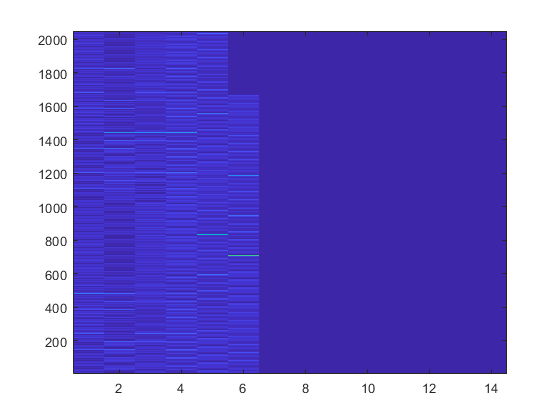

% rxdataF_symbol0;
% rxdataF0 = rxdataF;
% rxdataF_symbol1
% rxdataF0 = cat(1, rxdataF0, rxdataF);
% rxdataF_symbol2
% rxdataF0 = cat(1, rxdataF0, rxdataF);
% rxdataF_symbol3
% rxdataF0 = cat(1, rxdataF0, rxdataF);

figure;
imagesc(abs(reshape(rxdataF, [nfft symbols_per_slot]))); axis xy;

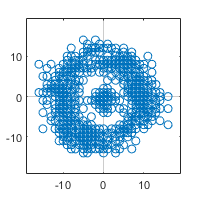

figure;
plotconst(rxdataF);